# Display_busVoltages.mlx

## This script will display precalculated analyses of grid parameters.

#### This script changes all interpretation parameters to LaTeX.

list_factory = fieldnames(get(groot,'factory'));
index_interpreter = find(contains(list_factory,'Interpreter'));
for i = 1:length(index_interpreter)
    default_name = strrep(list_factory{index_interpreter(i)},'factory','default');
    set(groot, default_name,'latex');
end

tic
folder_name = 'saved_outputs/'; %subfolder where data will be stored

system_name = 'ieee9'

system_name = 'ieee9'


tableName = strcat(folder_name, 'nominalValuesTable_',...
    system_name, '.csv');

nominalValuesTable = readtable(tableName);

% busesToPlot = 3;
% busesToPlot = [1 2 3 4 5 6 7 8 9];
busesToPlot = [1 2 3 5 8 9];

sampling_rate = nominalValuesTable.sampling_rate

sampling_rate = 0.0100

T = nominalValuesTable.T

T = 3

% T = 3
W = nominalValuesTable.W

W = 300


voltsTruncatedArrName = strcat(folder_name,'voltsTruncated_', ...
    system_name, '.mat');
voltsTruncatedArr = load(voltsTruncatedArrName);
voltsTruncatedArr = voltsTruncatedArr.voltsTruncatedArr;

bifurcationIdx = size(voltsTruncatedArr,1)

bifurcationIdx = 8438

indicesToPlotTruncated = 1:bifurcationIdx;
xaxisTruncated = (bifurcationIdx - indicesToPlotTruncated)...
    *sampling_rate/(60);

#### Subplot 1: Voltages obtained from the original run.

figure('Name', 'Complete Analysis of Bus Voltages.');
subplot(2,3,1);
plot(xaxisTruncated, voltsTruncatedArr(:, busesToPlot));
set(gca,'xdir','reverse')
title('Truncated Voltages (pu)');
xlabel('Time to Bifucation (min)');
ylabel('Voltage Magnitude (pu)');

name_labelVoltages = strcat(folder_name, 'labelVoltages_'...
    , system_name, '.mat');
labelVoltages = load(name_labelVoltages, "labelVoltages");
labelVoltages = labelVoltages.labelVoltages;
legend(labelVoltages(busesToPlot))

#### Subplot 2: Sp1 (Subplot 1) Voltages passed thru GKS filter.

subplot(2,3,2);

gks_voltsTruncatedArr = load(strcat(folder_name, 'gks_voltsTruncated_', ...
    system_name, '.mat'), 'gks_voltsTruncatedArr');
gks_voltsTruncatedArr = gks_voltsTruncatedArr.gks_voltsTruncatedArr;

convolutionMargin = floor(bifurcationIdx*0.005)

convolutionMargin = 42

indicesToPlotPostConvolution = 1+convolutionMargin:bifurcationIdx-W+1;
xaxisPostConvolution = (bifurcationIdx - indicesToPlotPostConvolution)...
    *sampling_rate/(60);
plot(xaxisPostConvolution, ...
    gks_voltsTruncatedArr(indicesToPlotPostConvolution, busesToPlot));
set(gca,'xdir','reverse')

title('Truncated Voltages after being passed thru GKS filter (pu)');
xlabel('Time to Bifucation (min)');
ylabel('Voltage Magnitude (pu)');

name_labelGKSVoltages = strcat(folder_name, 'labelGKSVoltages_'...
    , system_name, '.mat');
labelGKSVoltages = load(name_labelGKSVoltages, "labelGKSVoltages");
labelGKSVoltages = labelGKSVoltages.labelGKSVoltages;
legend(labelGKSVoltages(busesToPlot))

#### Subplot 3: Sp1 Voltages - Sp2 Voltages are displayed.

subplot(2,3,3);

voltsTruncatedDetrendedArrName = ...
    strcat(folder_name,'voltsTruncatedDetrended_', ...
    system_name, '.mat');
voltsTruncatedDetrendedArr = ...
    load(voltsTruncatedDetrendedArrName,'voltsTruncatedDetrendedArr');
voltsTruncatedDetrendedArr = ...
    voltsTruncatedDetrendedArr.voltsTruncatedDetrendedArr;

plot(xaxisPostConvolution, ...
    voltsTruncatedDetrendedArr(:, busesToPlot));

set(gca,'xdir','reverse')
title({['Detrended Voltages after subtracting '] ...
    ['the GKS signal from the original (pu)']});
xlabel('Time to Bifucation (min)');
ylabel('Detrended Voltages (pu)');

name_labelDeltaVoltages = strcat(folder_name, 'labelDeltaVoltages_'...
    , system_name, '.mat');
labelDeltaVoltages = load(name_labelDeltaVoltages, "labelDeltaVoltages");
labelDeltaVoltages = labelDeltaVoltages.labelDeltaVoltages;

#### Subplot 4: AR1(Sp3 Voltages)

ar1_vector = ...
    load(strcat(folder_name,'ar1_vector_bus_voltages_', ...
    system_name, '_', num2str(T), '_sec.mat'),'ar1_vector');

ar1_vector = ar1_vector.ar1_vector;

indicesToPlotPostParametrization = 1+convolutionMargin:bifurcationIdx-2*W+1;
xaxisPostParametrization = (bifurcationIdx - indicesToPlotPostParametrization)...
    *sampling_rate/(60);

subplot(2,3,4)
plot(xaxisPostParametrization, ar1_vector(:, busesToPlot));
% yyaxis left
set(gca,'xdir','reverse')
xlabel3 = xlabel('Time to bifurcation (minutes)');
% yticks3 = yticks;
ylabel3 = ylabel('$a_1$');
% ylabel3.Color = colors(1,:);
title('Autocorrelation values');

name_labelARDeltaVoltages = strcat(folder_name, 'labelARDeltaVoltages_'...
    , system_name, '.mat');
labelARDeltaVoltages = ...
    load(name_labelARDeltaVoltages, "labelARDeltaVoltages");
labelARDeltaVoltages = labelARDeltaVoltages.labelARDeltaVoltages;
legend(labelARDeltaVoltages(busesToPlot))

#### Subplot 5: Var(Sp3 Voltages)

var_vector = ...
    load(strcat(folder_name,'var_vector_bus_voltages_', ...
    system_name, '_', num2str(T), '_sec.mat'), 'var_vector');

var_vector = var_vector.var_vector;

subplot(2,3,5)
plot(xaxisPostParametrization, var_vector(:, busesToPlot));
% yyaxis left
set(gca,'xdir','reverse')
% yyaxis right
ylabel4 = ylabel('$\sigma^2$');
% ylabel4.Color = colors(2,:);
% yticks4 = yticks;
% set(gca,'ycolor',colors(2,:))
% set(gca,'xdir','reverse')
xlabel4 = xlabel('Time to bifurcation (minutes)');
title('Variance values');

name_labelVarDeltaVoltages = strcat(folder_name, 'labelVarDeltaVoltages_'...
    , system_name, '.mat');
labelVarDeltaVoltages =...
    load(name_labelVarDeltaVoltages, "labelVarDeltaVoltages");
labelVarDeltaVoltages = labelVarDeltaVoltages.labelVarDeltaVoltages;
legend(labelVarDeltaVoltages(busesToPlot))

#### Print the figure.

pdf_location_name = 'pdf/'

pdf_location_name = 'pdf/'

if T < 1
    windowInSec = strcat('point',string(10*T),'_sec');
else
    windowInSec = strcat(string(T),'_sec');
end
imagePdfName = strcat(pdf_location_name, '_', system_name,...
    'busVoltages_',num2str(busesToPlot),'_T_',windowInSec)

imagePdfName = "pdf/_ieee9busVoltages_1  2  3  5  8  9_T_3_sec"

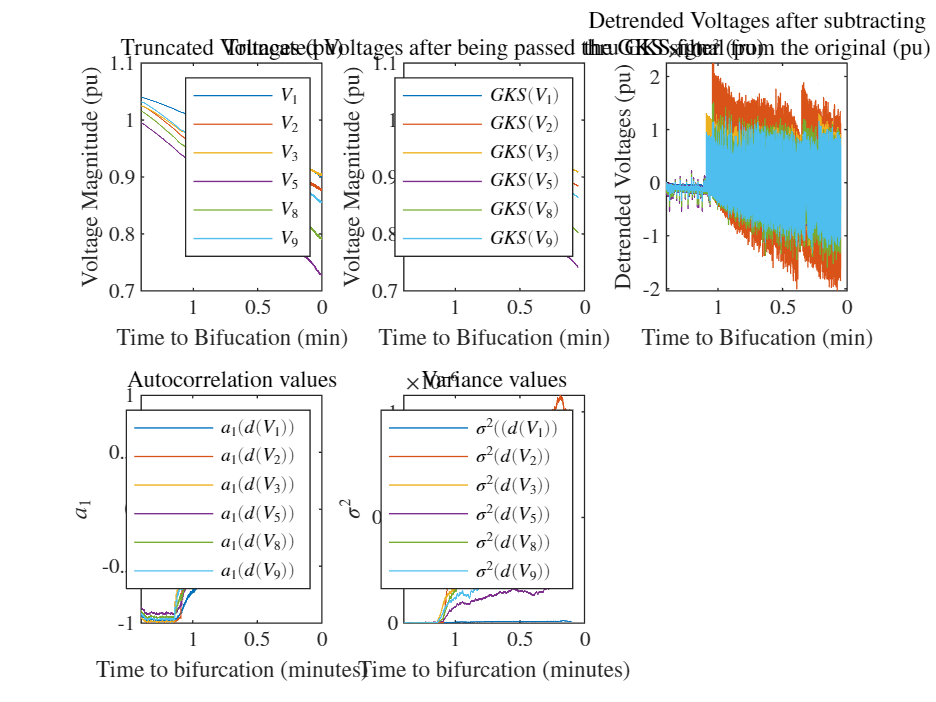


set(gcf, 'PaperSize', [24 12]); %set the paper size to what you want  
print(imagePdfName,'-dpdf', '-fillpage') % then print it